# ISET3d: Materials

PBRT scene materials are stored in a simple list attached to the scene **recipe**.  A material can be used to describe multiple objects in the scene.  Each object node (a leaf) has a slot that specifies the name of its material.  

We read and write material properties using the usual set/get method

When you read a PBRT scene from Cinema4D it has a list of materials, including matte, glass and mirror.  We are in the process of organizing the materials and adding more types so that we can read in pre-defined materials.  With PBRT V4.0 the types of materials will grow.

A material has many properties that define the object's color, surface roughness, specularity, and opacity. The color properties are separated in diffusion reflectance (kd), specular reflectance (ks), and mirror reflectance (kr).   We can specify the color in various ways, including RGB and spectral reflectance.

This tutorial illustrates how to set/get material properties and how to create new materials.

**See also**

  piMaterialCreate, t_assets, t_piIntro*

## The base scene

This is the low resolution simple scene. We will introduce a set of material changes

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 6 materials
Read 1 textures
Reading C4D geometry information.


thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5); 

piWrite(thisR);

Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene 
to 
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" --volume="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene":"/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  4.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


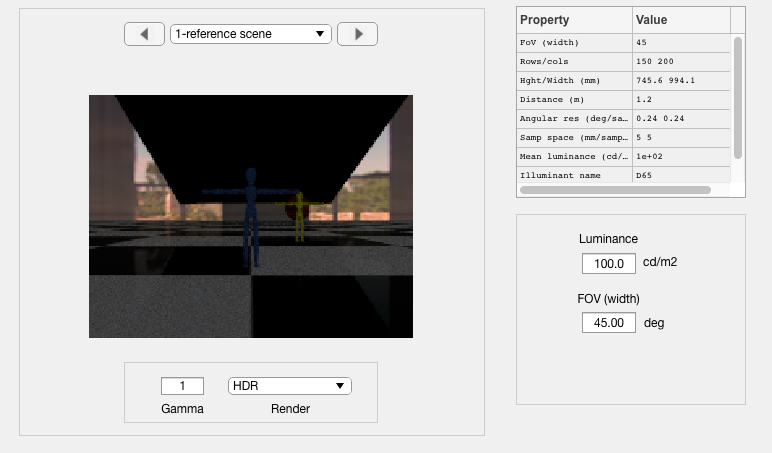

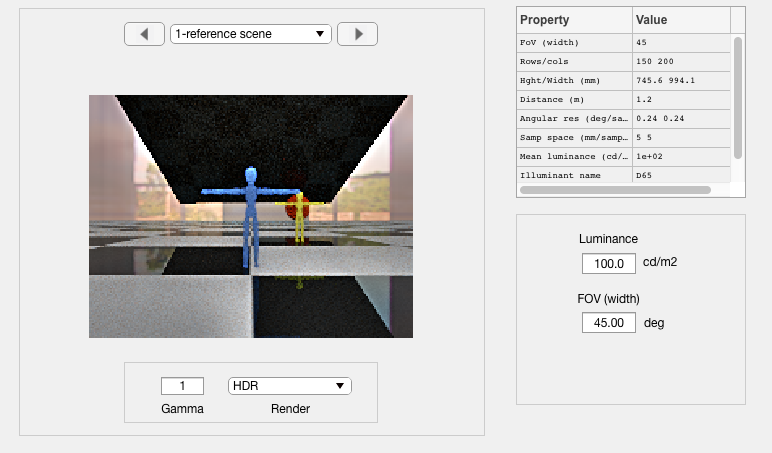

scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## List the scene materials

To list the materials in the scene, use this command

thisR.get('material print');


Materials in the scene SimpleScene
-------------------------------
  Name  	 [Type]
-------------------------------
1: uber_blue: 	 [ uber ]
2: uber: 	 [ uber ]
3: BODY: 	 [ uber ]
4: GLASS: 	 [ glass ]
5: mirror: 	 [ uber ]
6: Material: 	 [ uber ]
-------------------------------


## The material of an asset

Each asset (object node in the tree) has a material name.  We find the material for an object this way.

% The material of the blue stick figure
assetName = 'figure_3m_O'; 
thisR.get('asset',assetName,'material name')

ans = 'uber_blue'


% The material of the ceiling will become a mirror.  For now it is the black surface at the
% ceiling.
assetName = 'mirror_O';
thisR.get('asset',assetName,'material name')

ans = 'mirror'

## Material properties

We get a material from its name.  We can also get just a specific property.

% Find a material and print its properties
matName = 'uber_blue';
thisMat = thisR.get('material', matName)

thisMat = struct with fields:
              name: 'uber_blue'
      fluorescence: [1×1 struct]
     concentration: [1×1 struct]
              type: 'uber'
                kd: [1×1 struct]
                ks: [1×1 struct]
                kr: [1×1 struct]
                kt: [1×1 struct]
         roughness: [1×1 struct]
        uroughness: [1×1 struct]
        vroughness: [1×1 struct]
               eta: [1×1 struct]
           opacity: [1×1 struct]
    remaproughness: [1×1 struct]



% Check roughness
roughness = thisR.get('material', matName, 'roughness')

roughness = struct with fields:
     type: 'float'
    value: 0.5000



% Check diffuse property
kd = thisR.get('material', matName, 'kd')

kd = struct with fields:
     type: 'rgb'
    value: [0.0477 0.1075 0.3424]



% Check specular reflection property
ks = thisR.get('material', matName, 'ks')

ks = struct with fields:
     type: 'rgb'
    value: [0.0331 0.0331 0.0331]



% Check mirror reflection property
kt = thisR.get('material', matName, 'kr')

kt = struct with fields:
     type: 'rgb'
    value: [0.0331 0.0331 0.0331]



% Check the value of property kd
kdVal = thisR.get('material', matName, 'kd value')

kdVal =     0.0477    0.1075    0.3424



% Check property type
kdType = thisR.get('material', matName, 'kd type')

kdType = 'rgb'

## Set material color: RGB format

The blue guy wants to be green today.

% Change diffuse reflectance to be green
thisR.set('material', matName, 'kd value', [0 0.5 0]);

piWrite(thisR);

Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene 
to 
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" --volume="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene":"/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  9.7 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


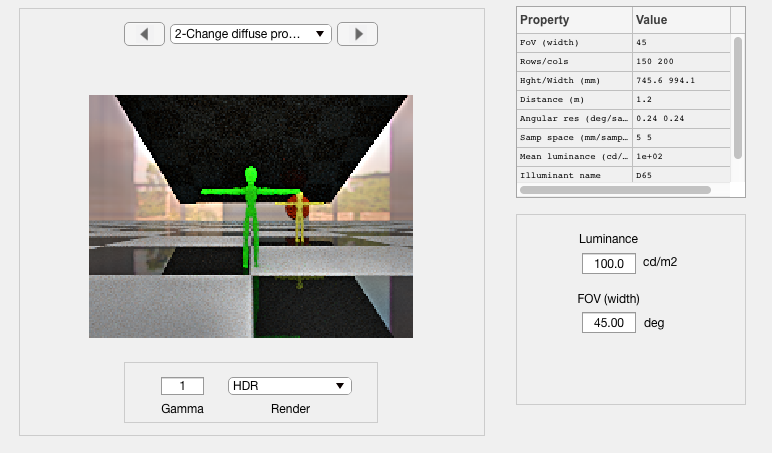

scene = sceneSet(scene, 'name', 'Change diffuse proerty');
sceneWindow(scene);

## Set material type: glass

The blue guy is feeling like glass.

% We are going to turn the blue stick figure into a glass figure.
glass = 'blueGuyGlass';
newMat = piMaterialCreate(glass, 'type', 'glass');
thisR.set('material', 'add', newMat);

% Find the figure asset
% n = thisR.assets.names;

assetName = 'figure_3m_O';
curName = thisR.get('asset', assetName, 'material name');
disp(['The current material is',curName]);

The current material isuber_blue



% We turn it into glass
thisR.set('asset', assetName, 'material name', glass);

piWrite(thisR);

Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene 
to 
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" --volume="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene":"/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  5.9 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


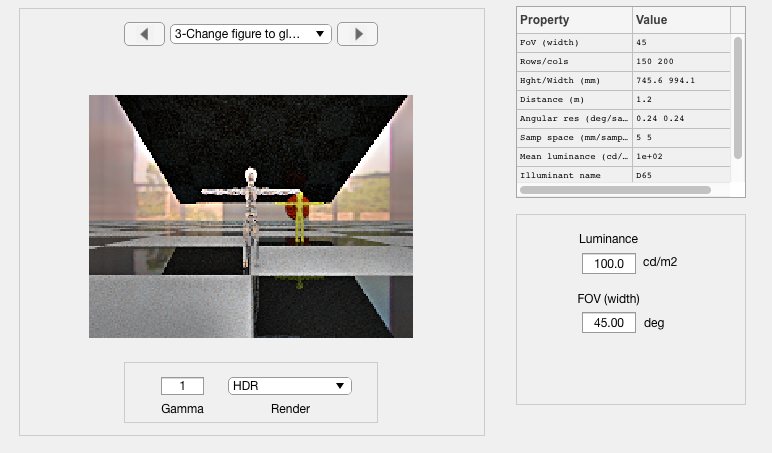

scene = sceneSet(scene, 'name', 'Change figure to glass');
sceneWindow(scene);

## Set material type: mirror

% Create a mirror material
materialName = 'newMirror';
newMat = piMaterialCreate(materialName, 'type', 'mirror');
thisR.set('material', 'add', newMat);

% This is the current black ceiling
assetName = 'mirror_O';
curName = thisR.get('asset', assetName, 'material name');

% And now we change it.
thisR.set('asset', assetName, 'material name', materialName);

% And render it
piWrite(thisR);

Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene 
to 
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" --volume="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene":"/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  5.9 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


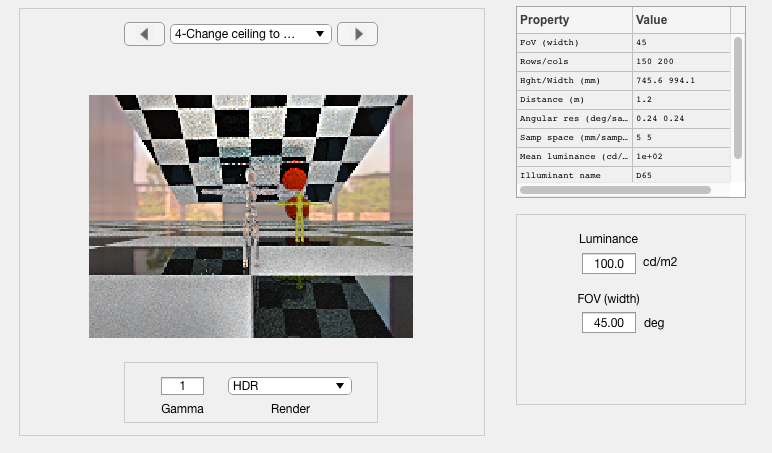

scene = sceneSet(scene, 'name', 'Change ceiling to mirror');
sceneWindow(scene);

## Set material spectral reflectance

We can also specify the color using a spectral reflectance function

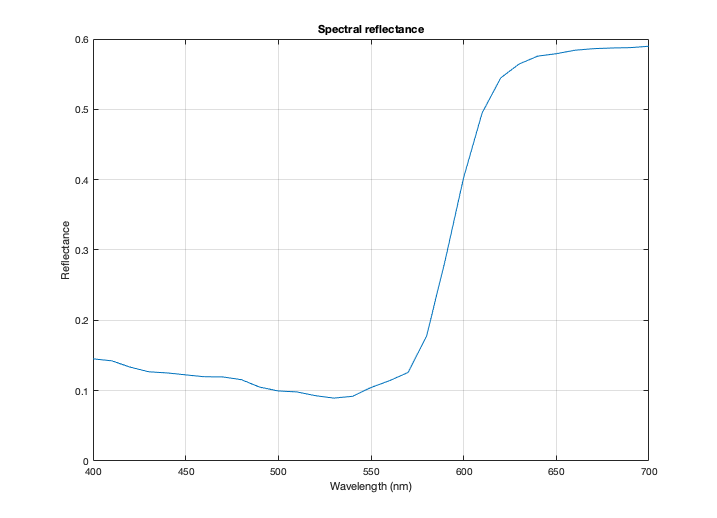

% This is still the ceiling
assetName = 'mirror_O';

% Set the spectral reflectance of the matte material to the reflectance of
% the 10th chip in the MCC.  It is very red.
wave = 400:10:700;
mccRefs = ieReadSpectra('macbethChart', wave);
thisRef = mccRefs(:, 10);
ieNewGraphWin;
plotReflectance(wave,thisRef);


redName = 'newMatte';
redMaterial = piMaterialCreate(redName, 'type', 'matte');
thisR.set('material', 'add', redMaterial);

% Convert the reflectance to the PBRT spd format.  It is (wave, value) ...
spdRef = piMaterialCreateSPD(wave, thisRef);

% Store the spd reflectance as the diffuse reflectance of the newMatte
% material
thisR.set('material', redName, 'kd value', spdRef);

% Assign the material to the asset
thisR.set('asset', assetName, 'material name', redName);

% Render
piWrite(thisR);

Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/zhenglyu/Desktop/Research/git/iset3d/data/V3/SimpleScene 
to 
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


[scene, res] = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" --volume="/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene":"/Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/zhenglyu/Desktop/Research/git/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  5.2 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


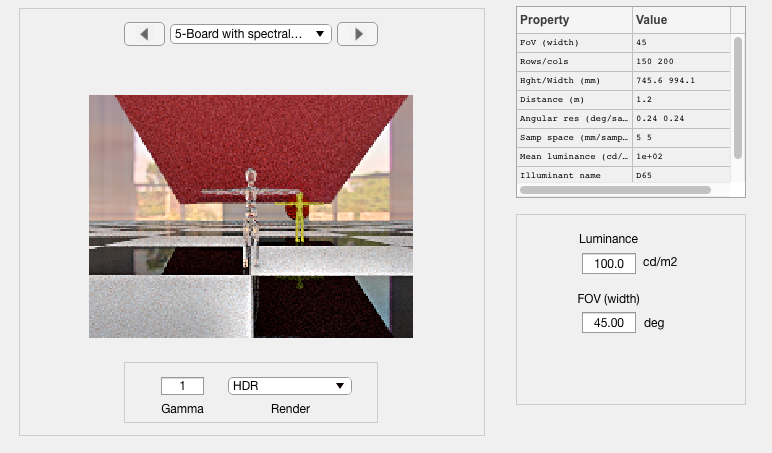

scene = sceneSet(scene, 'name', 'Board with spectral reflectance');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## Delete unused material

The blue guy never wants to be blue any more.

thisR.get('material print');


Materials in the scene SimpleScene
-------------------------------
  Name  	 [Type]
-------------------------------
1: uber_blue: 	 [ uber ]
2: uber: 	 [ uber ]
3: BODY: 	 [ uber ]
4: GLASS: 	 [ glass ]
5: mirror: 	 [ uber ]
6: Material: 	 [ uber ]
7: blueGuyGlass: 	 [ glass ]
8: newMirror: 	 [ mirror ]
9: newMatte: 	 [ matte ]
-------------------------------



% Delete uber_blue material
deleteName = 'uber_blue';
thisR.set('material', 'delete', deleteName);

% Check it's really deleted.
disp('uber_blue is deleted.')

uber_blue is deleted.


thisR.get('material print');


Materials in the scene SimpleScene
-------------------------------
  Name  	 [Type]
-------------------------------
1: uber: 	 [ uber ]
2: BODY: 	 [ uber ]
3: GLASS: 	 [ glass ]
4: mirror: 	 [ uber ]
5: Material: 	 [ uber ]
6: blueGuyGlass: 	 [ glass ]
7: newMirror: 	 [ mirror ]
8: newMatte: 	 [ matte ]
-------------------------------
